This script solves the 2-link robot ILC problem - see paper on Canvas for a background.

T = 0.001;  %Time step for solver
P = diag([50 50]);
L = diag([65 65]);
K = diag([2.5 2.5]);
Gam = [P,L,K];

Now I'll run the simulation to get the initial error.  The error should be the same as the desired trajectory (we're *learning* the reference from 0).

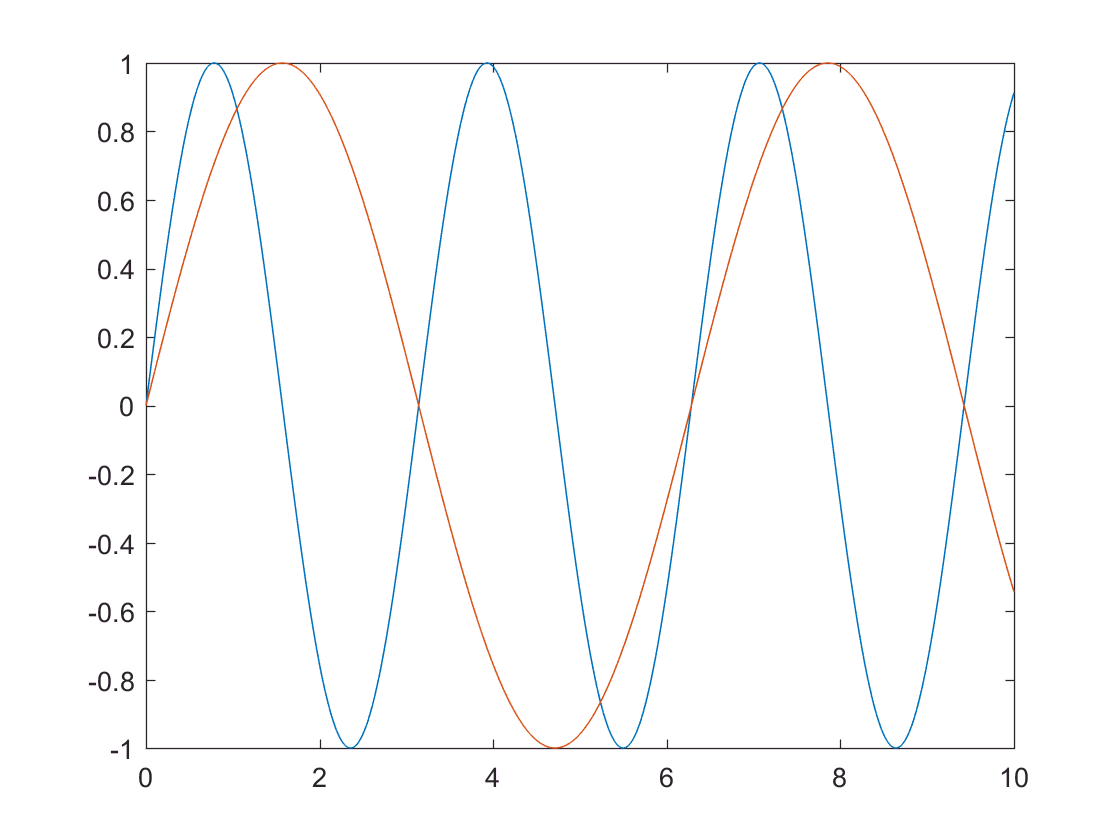

tvec = [0:T:10];
r_ILC = [tvec' zeros(length(tvec),1) zeros(length(tvec),1)];
sim('Nonlinear_ILC');
plot(tvec,[error(:,1),error(:,2)])

Now I'll run the ILC algorithm.  This works quite well, even though we've used no knowledge of the system!

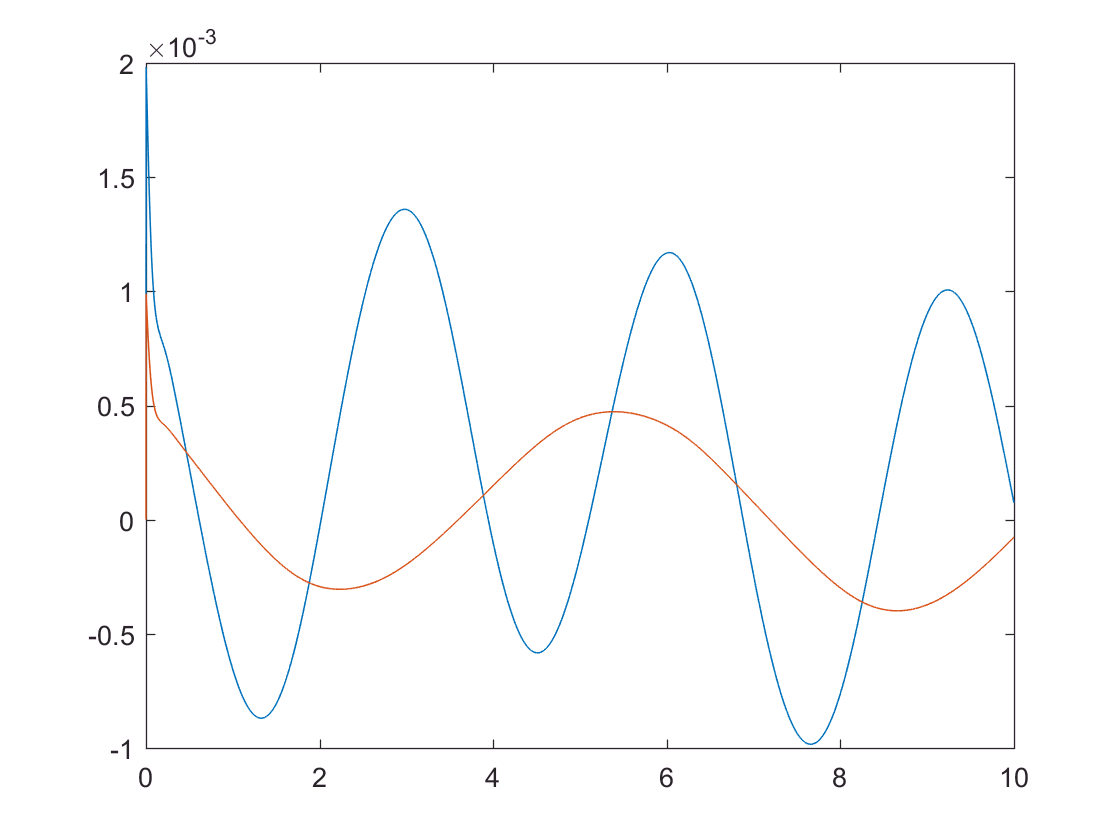

for ii = 1:5
    sim('Nonlinear_ILC');  %Get the data
    for ii = 1:length(tvec)
        r_ILC(ii,2:3) = r_ILC(ii,2:3)+(Gam*error(ii,:)')';  %Implement ILC
    end
end
plot(tvec,[error(:,1),error(:,2)])